clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

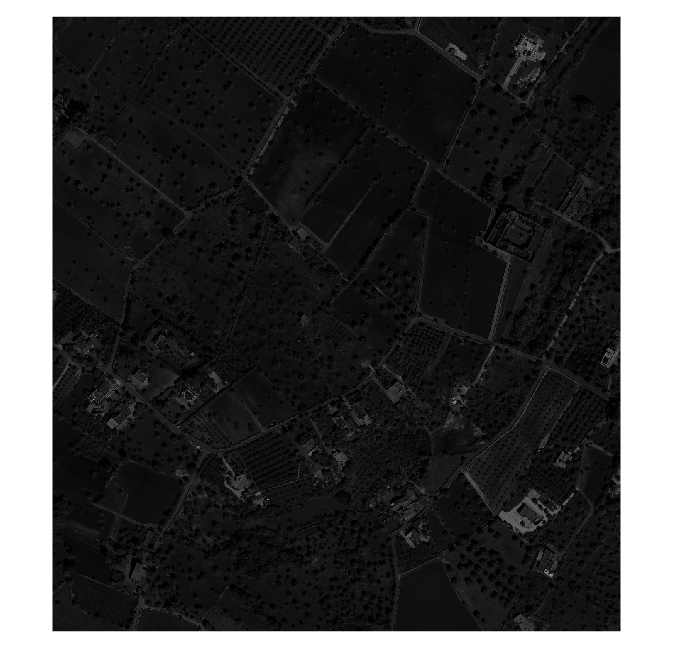

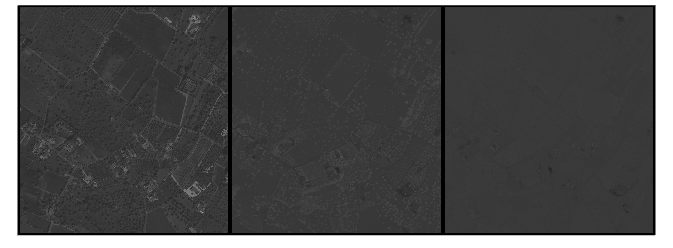

% Calculating PCA
[image,components] = PCA(hcube,5);

% k-means++ clustering
num_clusters = 5;

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% Set options
opts = statset('Display','final','MaxIter',50000, 'TolFun',1e-6);

% Run k-means++ with 'plus' option
[idx, centers] = kmeans(pixels, num_clusters, 'Start', 'plus', 'Options', opts);

Replicate 1, 65 iterations, total sum of distances = 59874.6.


Best total sum of distances = 59867.9


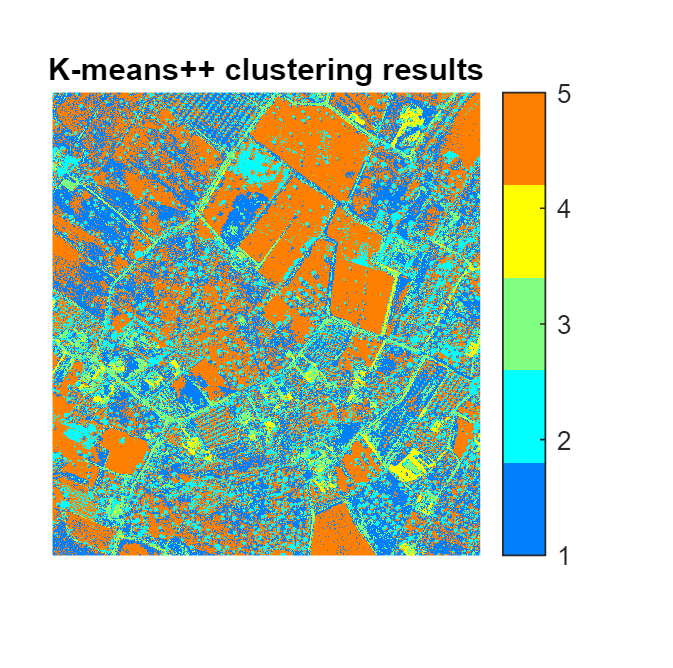


% Obtaining image's sizes
[rows, cols, ~] = size(image);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(num_clusters));
colorbar;
title('K-means++ clustering results');